% ------------------------------ BEGIN CODE -------------------------------

disp("BENCHMARK: TORA Heterogeneous (tanh)")

BENCHMARK: TORA Heterogeneous (tanh)



% Parameters --------------------------------------------------------------

R0 = interval([-0.77;-0.45;0.51;-0.3],[-0.75;-0.43;0.54;-0.28]);

params.tFinal = 5;
params.R0 = polyZonotope(R0);

% Reachability Settings ---------------------------------------------------

options.timeStep = 0.05;
options.alg = 'lin';
options.tensorOrder = 3;
options.taylorTerms = 4;
options.zonotopeOrder = 200;
options.errorOrder = 10;
options.intermediateOrder = 50;

% Parameters for NN evaluation --------------------------------------------

evParams = struct();
evParams.poly_method = "singh";

% System Dynamics ---------------------------------------------------------

% open-loop system
f = @(x,u) [x(2); -x(1) + 0.1*sin(x(3)); x(4); u(1) * 11];
sys = nonlinearSys(f);

% load neural network controller

nn = neuralNetwork.readONNXNetwork('/Users/rayenmhadhbi/PycharmProjects/nn_verification/TORA/cora/actor_model_tora_second_network_second_reward_fixed_state16.onnx');

% construct neural network controlled system
sys = neurNetContrSys(sys, nn, 0.5);

% Specification -----------------------------------------------------------

goalSet = interval([-0.1;-0.9;-Inf;-Inf], [0.2;-0.6;Inf;Inf]);
spec = specification(goalSet, 'safeSet', interval(params.tFinal));
% Verification ------------------------------------------------------------

t = tic;
[res, R, simRes] = verify(sys, spec, params, options, evParams, true);

Time to compute random simulations: 0.36278
Time to check violation in simulations: 0.21165
Time to compute reachable set: 5.7907
Time to check verification: 0.067642
Total Time: 6.4328


%R = reach(sys, params, options, evParams, spec);
tTotal = toc(t);
disp(['Result: ' res])

Result: VERIFIED



% Visualization -----------------------------------------------------------

disp("Plotting..")

Plotting..


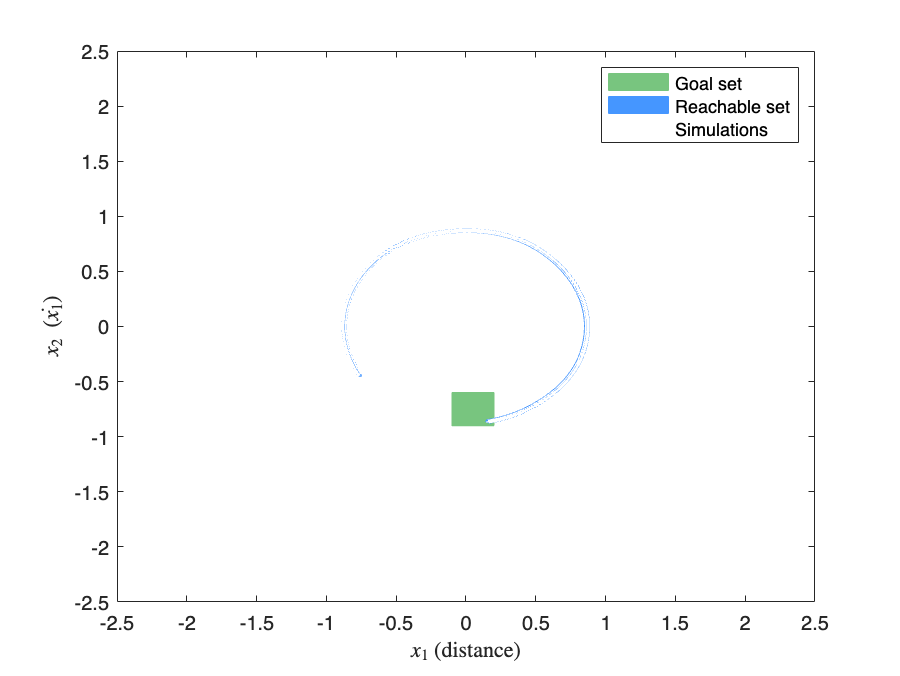

figure; hold on; box on;
projDims = [1, 2];

% plot specifications
plot(spec, projDims, 'DisplayName', 'Goal set');

% plot reachable set
useCORAcolors("CORA:contDynamics")
 plot(R, projDims, 'DisplayName', 'Reachable set');

% plot initial set
%plot(R(1).R0, projDims, 'DisplayName', 'Initial set');

% plot simulations
plot(simRes, projDims, 'DisplayName', 'Simulations');

% labels, limits, and legend
xlabel('$x_1$ (distance)', 'interpreter', 'latex');
ylabel('$x_2\ (\dot{x_1})$', 'interpreter', 'latex')
xlim([-2.5, 2.5]);
ylim([-2.5, 2.5]);
legend()